%% RPTU Paritásellenőrző Mátrix ($H$) beolvasása és szimulációja
% Ez a szkript bemutatja, hogyan dolgozzuk fel az RPTU adatbázisból származó
% kicsomagolt (.txt) formátumú fájlokat, és hogyan szimuláljuk le rajtuk a csatornakódolást.

%%@misc{channelcodes,
%author = "Helmling, Michael and Scholl, Stefan and Gensheimer, Florian and Dietz, Tobias and Kraft, Kira and Griebel, Oliver and Ruzika, Stefan and Wehn, Norbert",
%title = "{D}atabase of {C}hannel {C}odes and {ML} {S}imulation {R}esults",
%howpublished = "\url{www.rptu.de/channel-codes}",
%year = "2025"
%}

clear; clc; close all;

%% 1. Fájlnév megadása
% Ez a .txt fájl egy hagyományos (sűrű) mátrixot tartalmaz 0-kkal és 1-esekkel.
hFilename = 'LTE_TC_N132_K40.txt';

%% 2. A fájl beolvasása és Sparse Mátrix generálása (A parser)
fprintf('--- Fájl feldolgozása ---\n');

--- Fájl feldolgozása ---


% A beolvasás sokkal egyszerűbb, mivel sűrű mátrix formátumról van szó:
H_dense = readmatrix(hFilename);

% A MATLAB LDPC dekódolója ritka (sparse) LOGIKAI (logical) mátrixot vár,
% ezért átkonvertáljuk a számokat logikai értékekké a ritkítás előtt:
H_sparse = sparse(logical(H_dense));

% Méretek meghatározása
[M, N] = size(H_sparse); 
K = N - M; % Hasznos bitek száma (közelítés, ha H teljes rangú)
kodarany = K / N;

fprintf('Mátrix mérete: %d oszlop (N), %d sor (M)\n', N, M);

Mátrix mérete: 132 oszlop (N), 92 sor (M)


fprintf('Kódarány: ~%.2f\n\n', kodarany);

Kódarány: ~0.30




% Opcionális: a sparse mátrix mentése MATLAB natív formátumba a jövőre nézve
save('rptu_matrix.mat', 'H_sparse'); 

%% 3. Kommunikációs Szimuláció beállítása
% Használjuk a "Csupa-Nulla" trükköt, hogy ne kelljen a Generátor mátrixszal (G) 
% vesződni. Csupa 0-t küldünk.

snr_dB_array = 0:2:8; % Szimulált Jel-Zaj viszonyok (SNR) decibelben
max_hibas_blokk = 50; % Hány hibás keretig fusson egy SNR ponton
max_keret = 10000;    % Maximum hány keretet küldjünk
ber_results = zeros(size(snr_dB_array));

% Dekódoló beállítása: A MATLAB beépített üzenettovábbító (Belief Propagation) 
% LDPC dekódoló konfigurációját használjuk a mátrixunkhoz az új ldpcDecode függvénnyel.
cfgLDPCDec = ldpcDecoderConfig(H_sparse);
max_iter = 20; % Maximum iterációk száma a dekódoláshoz

fprintf('--- Szimuláció indítása (All-Zero Codeword trükkel) ---\n');

--- Szimuláció indítása (All-Zero Codeword trükkel) ---


for snr_idx = 1:length(snr_dB_array)
    snr = snr_dB_array(snr_idx);
    hiba_szam = 0;
    bit_szam = 0;
    hibas_blokkok = 0;
    
    for keret = 1:max_keret
        % 1. Adat "generálása" és Moduláció (Csupa 0 bit -> Csupa +1 szimbólum)
        % BPSK: 0 bit -> +1 feszültség, 1 bit -> -1 feszültség
        tx_szimbolumok = ones(N, 1); 
        
        % 2. Csatorna zaj (AWGN)
        % A zajos jelünk (LLR - Log Likelihood Ratio alapja)
        rx_szimbolumok = awgn(tx_szimbolumok, snr, 'measured');
        
        % Vételi valószínűségek konvertálása LLR-ré
        % A pontos LLR képlet BPSK és AWGN esetén: LLR = 2 * y / sigma^2
        zaj_teljesitmeny = 10^(-snr/10); % A csatorna zajának varianciája
        rx_llr = 2 * rx_szimbolumok / zaj_teljesitmeny; 
        
        % 3. Dekódolás a paritásmátrix (H) konfigurációja alapján
        rx_bitek = ldpcDecode(rx_llr, cfgLDPCDec, max_iter);
        
        % 4. Hibaszámítás
        % Mivel csupa 0-t küldtünk, minden 1-es bit, amit a dekódoló kiad, HIBA.
        hibak_a_keretben = sum(rx_bitek);
        hiba_szam = hiba_szam + hibak_a_keretben;
        bit_szam = bit_szam + K; % A dekódoló K bitet ad vissza
        
        if hibak_a_keretben > 0
            hibas_blokkok = hibas_blokkok + 1;
        end
        
        if hibas_blokkok >= max_hibas_blokk
            break; % Elég statisztika gyűlt össze ehhez az SNR-hez
        end
    end
    
    ber_results(snr_idx) = hiba_szam / bit_szam;
    fprintf('SNR = %d dB | BER = %e | Értékelt keretek: %d\n', snr, ber_results(snr_idx), keret);
end

SNR = 0 dB | BER = 8.948864e-02 | Értékelt keretek: 88
SNR = 2 dB | BER = 3.193182e-02 | Értékelt keretek: 220
SNR = 4 dB | BER = 1.852410e-02 | Értékelt keretek: 332
SNR = 6 dB | BER = 7.444314e-03 | Értékelt keretek: 853
SNR = 8 dB | BER = 3.498759e-03 | Értékelt keretek: 2015


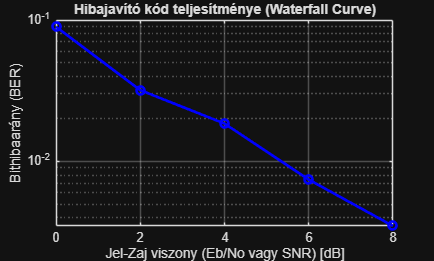


%% 4. Eredmények kirajzolása (Vízesés görbe / Waterfall curve)
figure('Name', 'RPTU Kód Teljesítménye', 'NumberTitle', 'off');
semilogy(snr_dB_array, ber_results, 'b-o', 'LineWidth', 2);
grid on;
xlabel('Jel-Zaj viszony (Eb/No vagy SNR) [dB]');
ylabel('Bithibaarány (BER)');
title('Hibajavító kód teljesítménye (Waterfall Curve)');